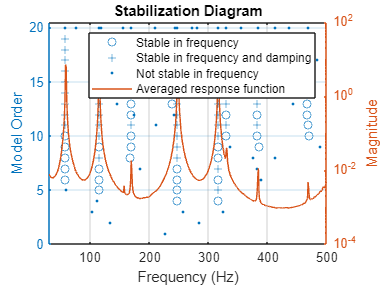

% Step 1: Load the data
load('ScanChrip20_600Hz_1s.mat');

% Step 2: Estimate the spectral transfer functions (FRF)
n = size(Sila, 1);  % Number of samples
m = size(Sila, 2);  % Number of measurement points
fs = 1280;  % Sampling frequency

% Initialize the FRF matrix
FRF = zeros(n, m);

% Calculate the Fourier transform for each measurement point
for i = 1:m
    ForceF = fft(Sila(:, i), [], 1);
    PredF = fft(Pred(:, i), [], 1);
    FRF(:, i) = PredF ./ ForceF;
end

% Create the frequency vector
FREQ = (0:n-1)*(fs/n);

% Step 3: Limit the frequency range to 0 to fs/2
half_n = floor(n/2) + 1;
FRF = FRF(1:half_n, :);
FREQ = FREQ(1:half_n);

% Step 4: Create the stabilization diagram
FreqRange = [30, 500];
modalsd(FRF, FREQ, fs, 'FreqRange', FreqRange, 'MaxModes', 20, 'FitMethod', 'lsce');

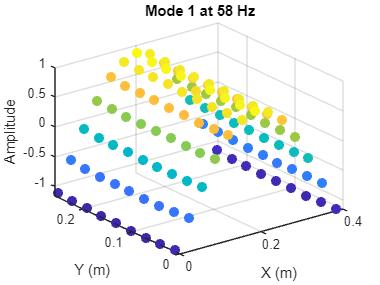

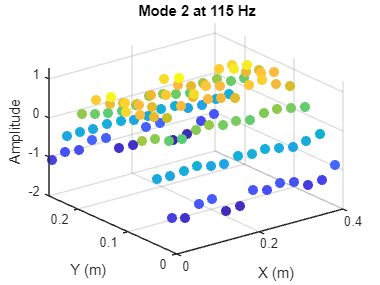

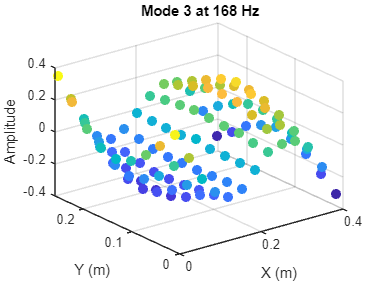

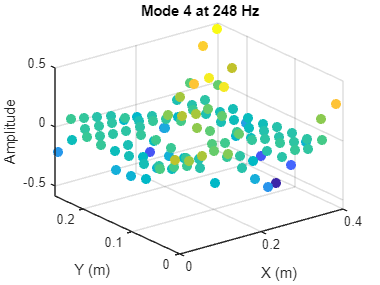

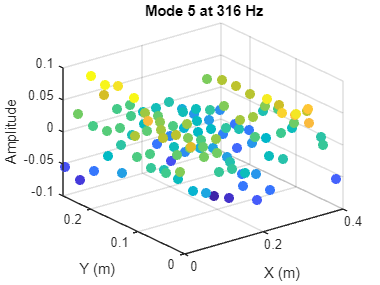

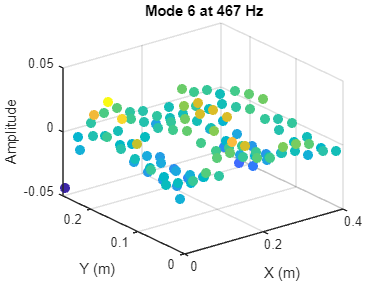

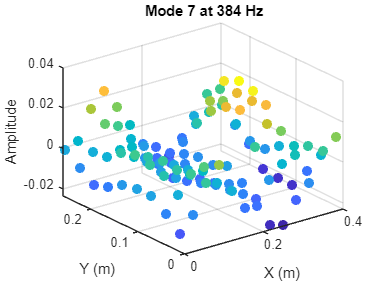


% Step 5: Read the stable eigenfrequencies from the diagram
% Note: Manual step - inspect the stabilization diagram to find stable frequencies
PF = [58, 115, 168, 248, 316, 467, 384]; % Example frequencies (replace with actual values from the diagram)

% Step 6: Estimate the vibration modes
[FN, DR, MS] = modalfit(FRF, FREQ, fs, 20, 'FreqRange', FreqRange, 'FitMethod', 'lsce', 'PhysFreq', PF);

% Extract the imaginary part of the MS matrix for visualization
ImMS = imag(MS);

% Visualize each mode of vibration with optional inversion
invert_modes = true;  % Set this to true or false depending on the sign convention

for i = 1:length(PF)
    ModeSel = ImMS(:, i);
    if invert_modes
        ModeSel = -ModeSel;
    end
    
    figure;
    scatter3(X, Y, ModeSel, 500, ModeSel, '.');
    title(['Mode ', num2str(i), ' at ', num2str(PF(i)), ' Hz']);
    xlabel('X (m)');
    ylabel('Y (m)');
    zlabel('Amplitude');
end

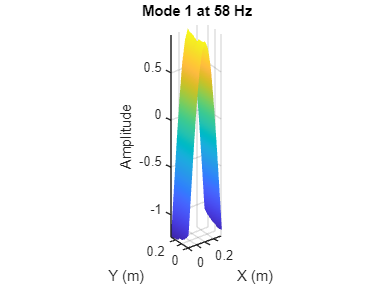

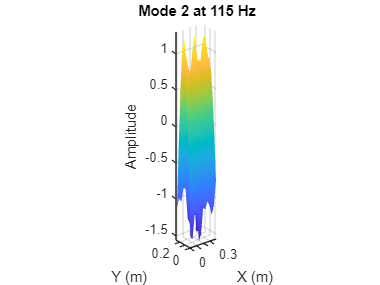

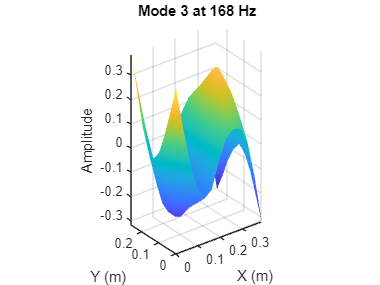

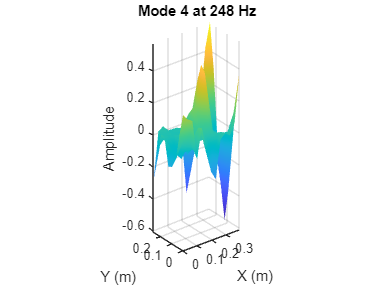

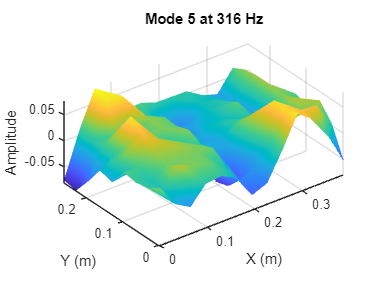

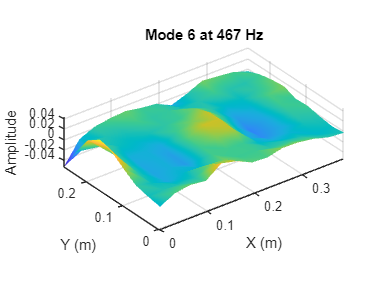

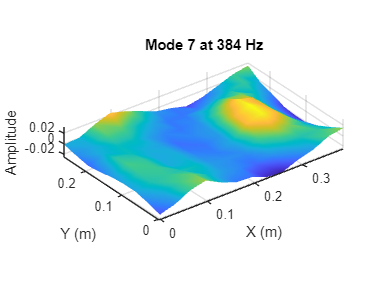


% Create a grid for better visualization of modes with optional inversion
xnodes = linspace(min(X), max(X), 13);
ynodes = linspace(min(Y), max(Y), 9);

for i = 1:length(PF)
    ModeSel = ImMS(:, i);
    if invert_modes
        ModeSel = -ModeSel;
    end
    
    [zgrid, xgrid, ygrid] = gridfit(X, Y, ModeSel, xnodes, ynodes);
    
    figure;
    surf(xgrid, ygrid, zgrid);
    shading interp;
    axis equal tight;
    title(['Mode ', num2str(i), ' at ', num2str(PF(i)), ' Hz']);
    xlabel('X (m)');
    ylabel('Y (m)');
    zlabel('Amplitude');
end